% This script was used to assess network output. A variety of different
% quantiative metrics were extracted from the network output, all shown
% within this code.

% MPhys Research Project 2022/23
% Ross Anderson (H00295702)



% clear commands
clc
clear
close all

% set the run number, this is indicated by the gdrive file
run_no = 23;

% % load all aspects of that run
% load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\results.mat");
% % load("G:\My Drive\MPhys Project\run_"+run_no+"\history.mat");
% images_sampled_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\centroid.mat");
% images_gaussfilt_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\gaussfilt.mat");
% % images_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\images.mat");
% coeffs = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\coeffs.mat");
% % coeffs = coeffs.coeffs;

count_level = "10^1";

load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\"+count_level+"\\results_process.mat");
% load("G:\My Drive\MPhys Project\run_"+run_no+"\history.mat");
images_sampled_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\"+count_level+"\\centroid_process.mat");
images_gaussfilt_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\"+count_level+"\\gaussfilt_process.mat");
% images_mat = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\images.mat");
coeffs = load("G:\My Drive\MPhys Project\centroid\run_"+run_no+"\"+count_level+"\\coeffs_process.mat");

images_sampled_mat = images_sampled_mat.images_sampled_mat;
images_gaussfilt_mat = images_gaussfilt_mat.images_gaussfilt_mat;

% convert the network_output in the correct dimensionality
network_output = results.predictions;
network_output = permute(network_output, [2, 3, 1]);

count_level = coeffs.coeffs.counts;

find(count_level == min(count_level(1:100)))

ans =     37   317


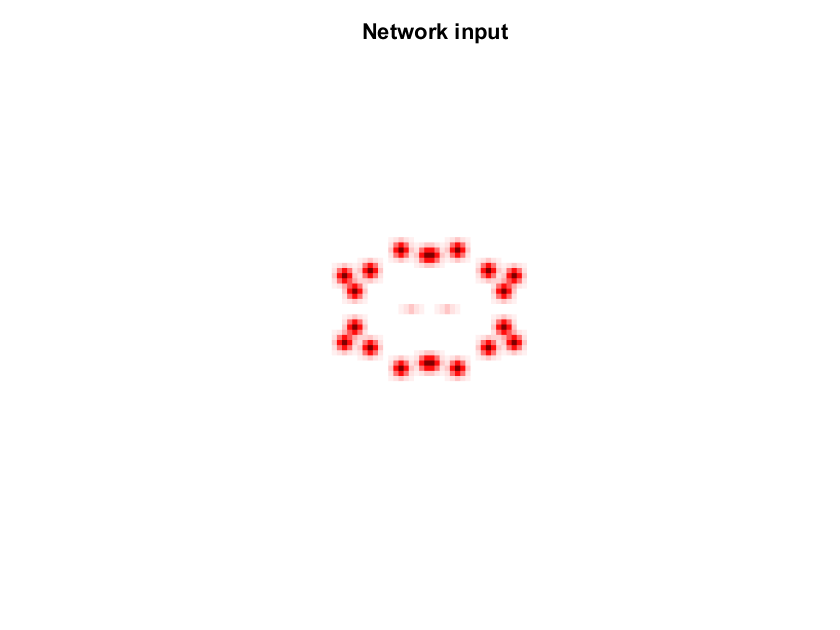


% choose image to analyse
N = 5;
N_val = N;


% use 4-fold symmetry to assemble full images
gaussfilt_tot = flipcat_4fold(images_gaussfilt_mat(:,:,N));
showim(gaussfilt_tot, 1)
title("Network input")
shading flat

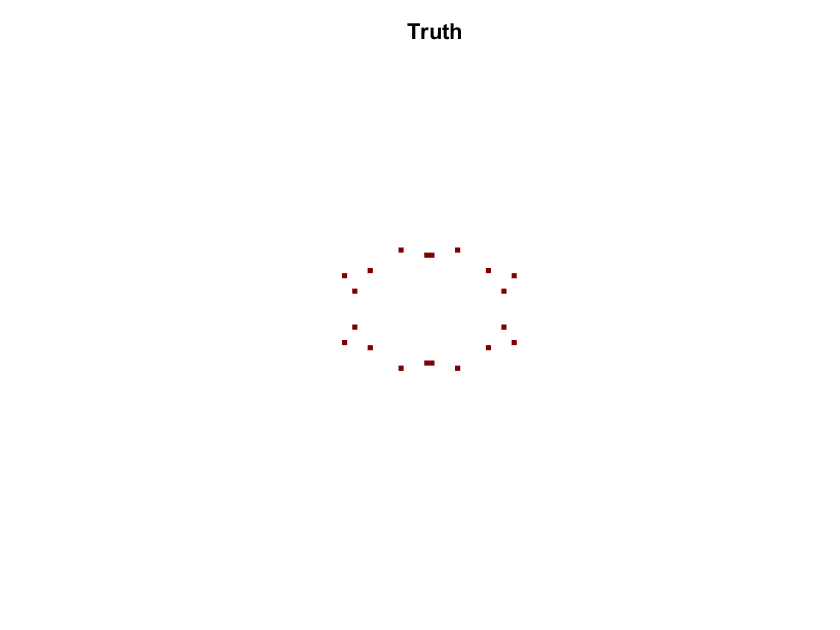


sampled_tot = flipcat_4fold(images_sampled_mat(:,:,N));
showim(sampled_tot, 1)
title("Truth")
shading flat

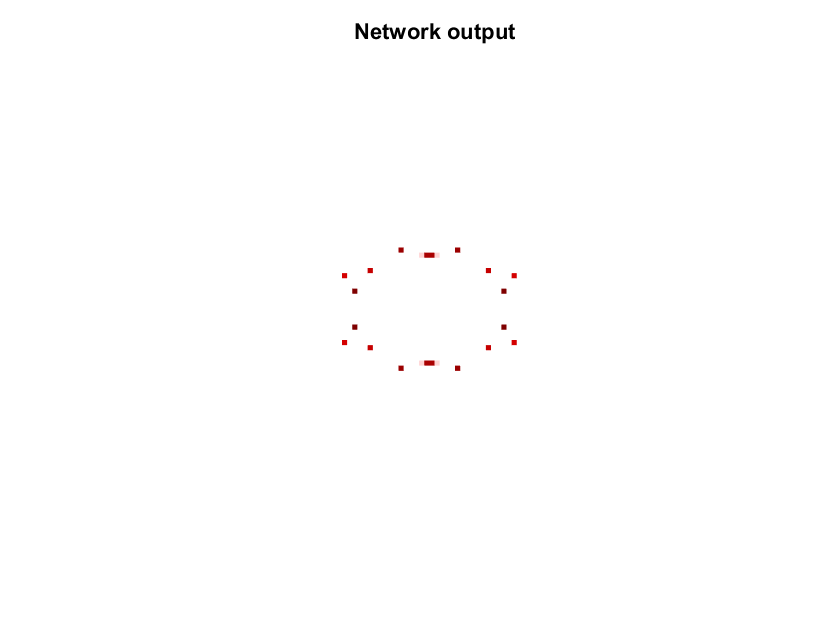


network_output_tot = flipcat_4fold(network_output(:, :, N_val));
showim(network_output_tot, 1)
title("Network output")
shading flat

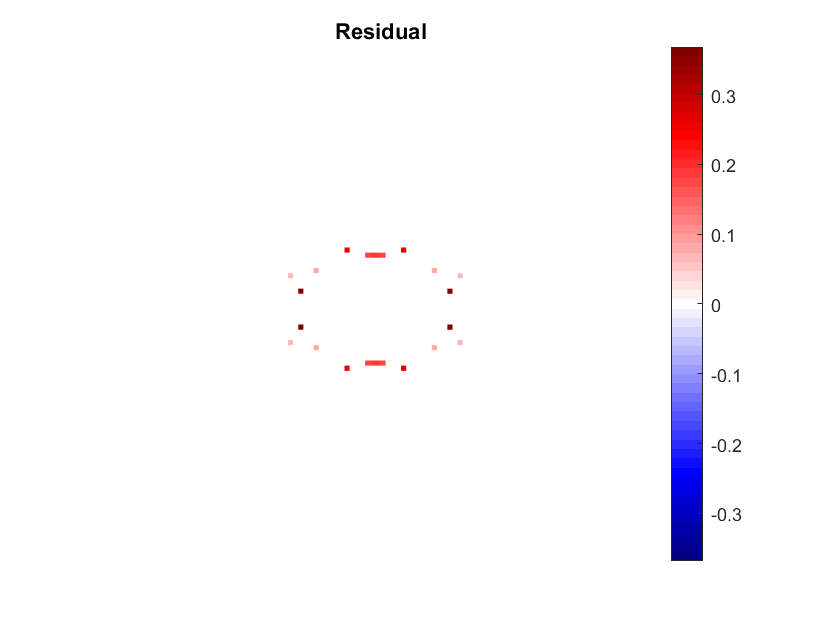


residual = network_output_tot - sampled_tot;
showim(residual, 1)
title("Residual")
colorbar
shading flat

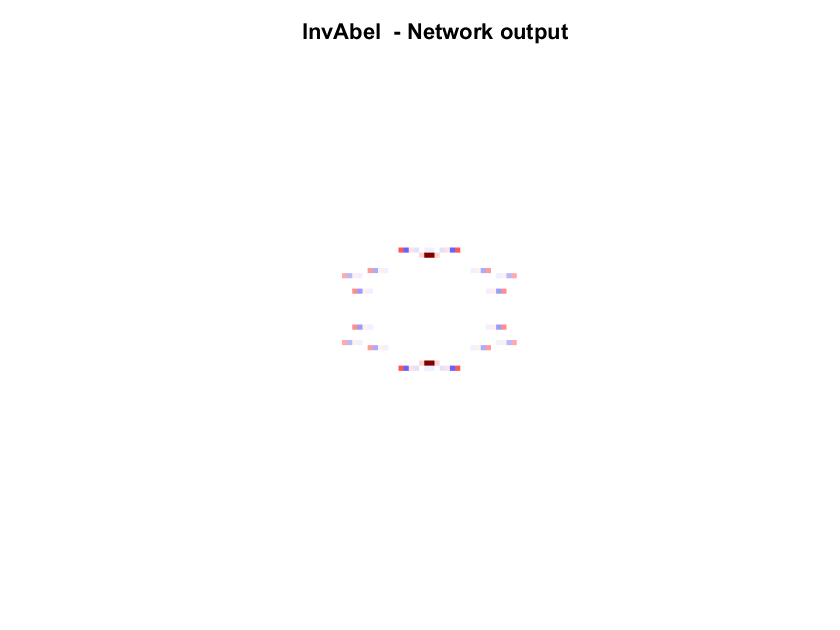



rmse = sqrt(mean((sampled_tot(:)-network_output_tot(:)).^2));
rmse_network = sqrt(mean((gaussfilt_tot(:)-network_output_tot(:)).^2));


% -----------------------------------------------------------------------------------------------

% % plot the loss
% figure()
% plot(loss)
% hold on
% plot(val_loss)
% legend("Loss", "Validation Loss")
% xlabel("Epoch")
% ylabel("Loss")

% -----------------------------------------------------------------------------------------------

% inverse Abel invert (invAbel) the network output
inverted_output = InvAbel(network_output_tot);
showim(inverted_output, 1);
title("InvAbel  - Network output")
shading flat

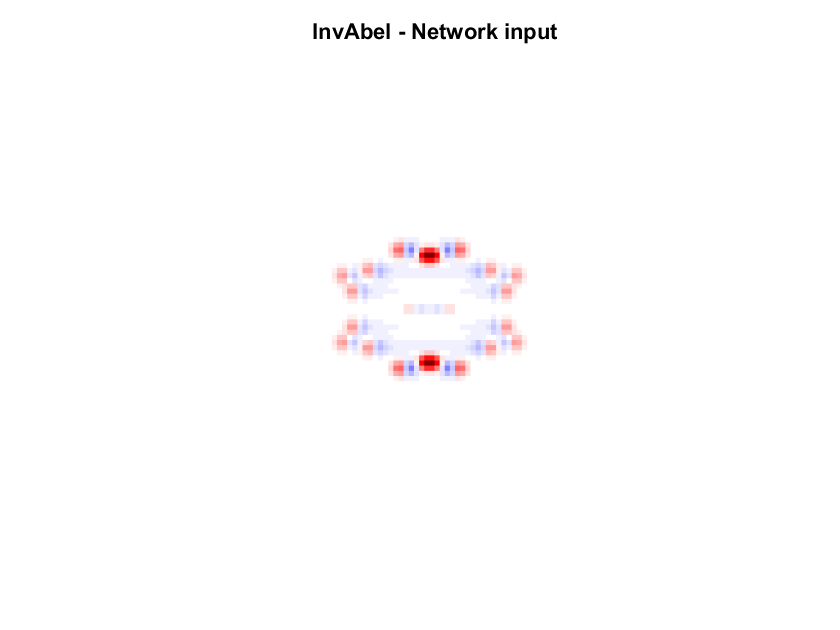


% integrate network output over all radii and angles
[integrated_output, interp_integrated_output, radii, theta_whole]   = integrateim(inverted_output);

% -----------------------------------------------------------------------------------------------

% invAbel the network input
inverted_network_input = InvAbel(gaussfilt_tot);
showim(inverted_network_input, 1)
title("InvAbel - Network input")
shading flat

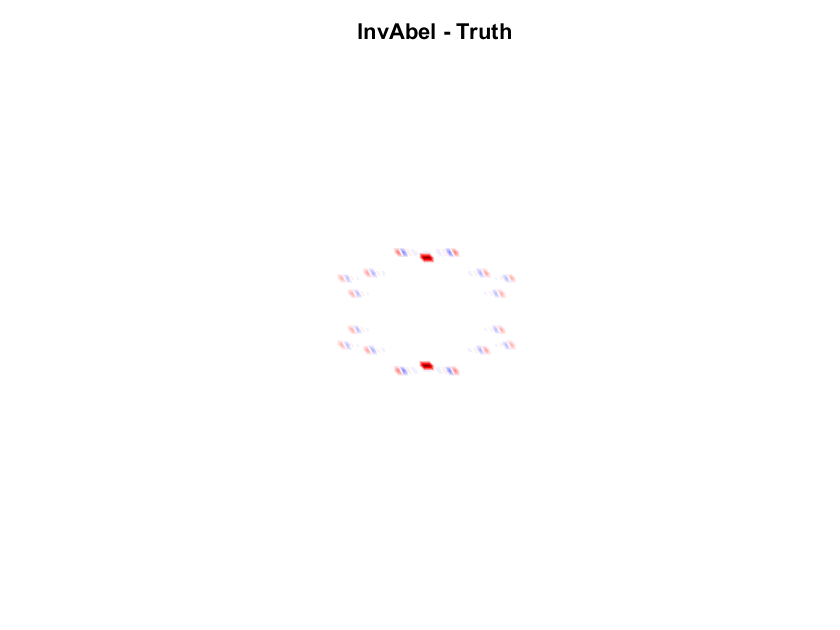


%integrate network input over all radii and angles
[integrated_input, interp_integrated_input, radii, theta_whole] = integrateim(inverted_network_input);

% -----------------------------------------------------------------------------------------------

% % invAbel the original image prior to blurring
% images_mat = images_mat.images_mat;
% before_blurring = images_mat(:, :, N);
% inverted_before_blurring = InvAbel(before_blurring);
% showim(before_blurring, 1)
% title("Image before blurring")
% showim(inverted_before_blurring, 1)
% title("InvAbel of image before blurring")
%
% % integrate original image before blurring over all radii and angles
% [integrated_before_blurring, interp_integrated_before_blurring, radii, theta_whole] = integrateim(inverted_before_blurring);

% -----------------------------------------------------------------------------------------------

inverted_truth = InvAbel(sampled_tot);
showim(inverted_truth, 1);
title("InvAbel - Truth")

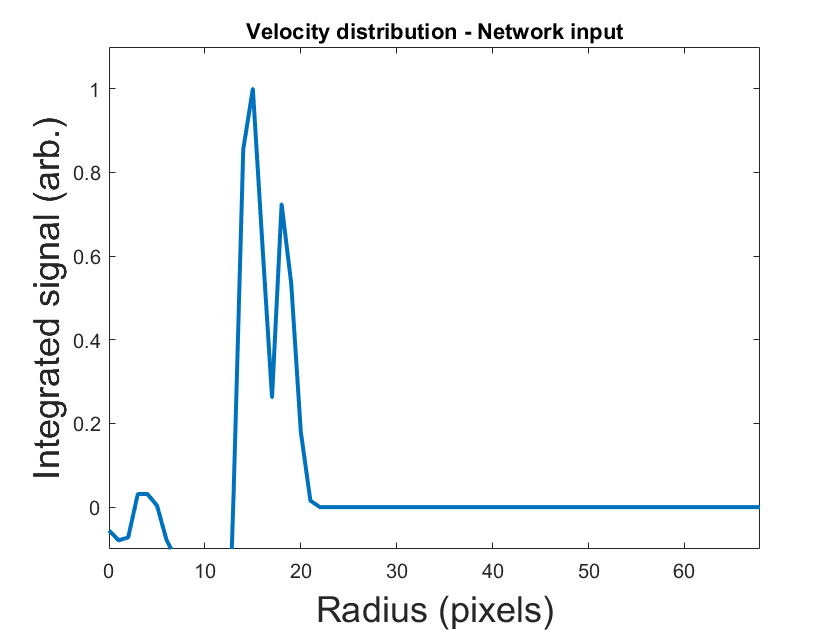


[integrated_truth, interp_integrated_truth, radii, theta_whole] = integrateim(inverted_truth);


% -----------------------------------------------------------------------------------------------




% plot the velocity distributions

% network input
figure()
interp_integrated_input = interp_integrated_input/max(interp_integrated_input);
plot(radii, interp_integrated_input, "LineWidth", 2)
title("Velocity distribution - Network input")
xlim([0, max(radii)])
% xlim([0, 40])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

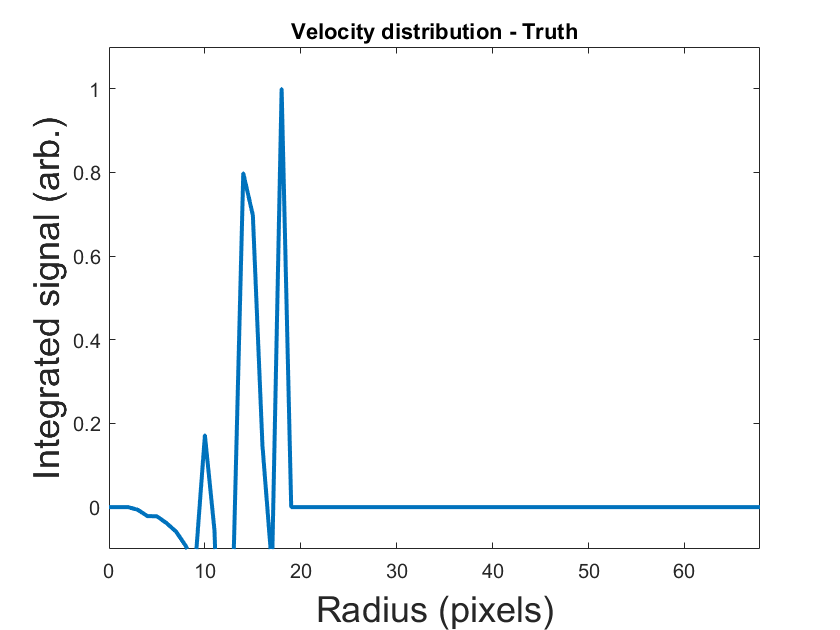



%truth
figure()
interp_integrated_truth = interp_integrated_truth/max(interp_integrated_truth);
plot(radii, interp_integrated_truth, "LineWidth", 2)
title("Velocity distribution - Truth")
xlim([0, max(radii)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

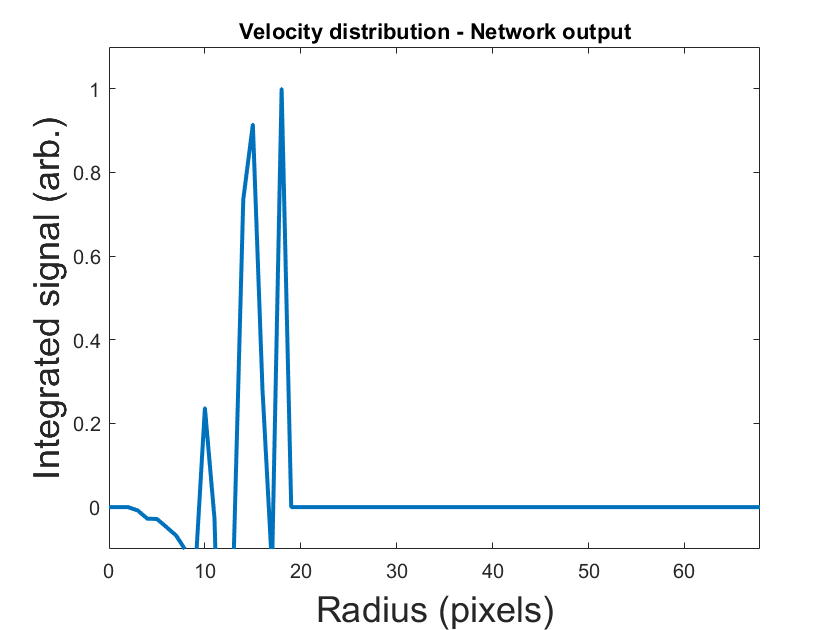



% network output
figure()
interp_integrated_output = interp_integrated_output/max(interp_integrated_output);
plot(radii, interp_integrated_output, "LineWidth", 2)
title("Velocity distribution - Network output")
xlim([0, max(radii)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

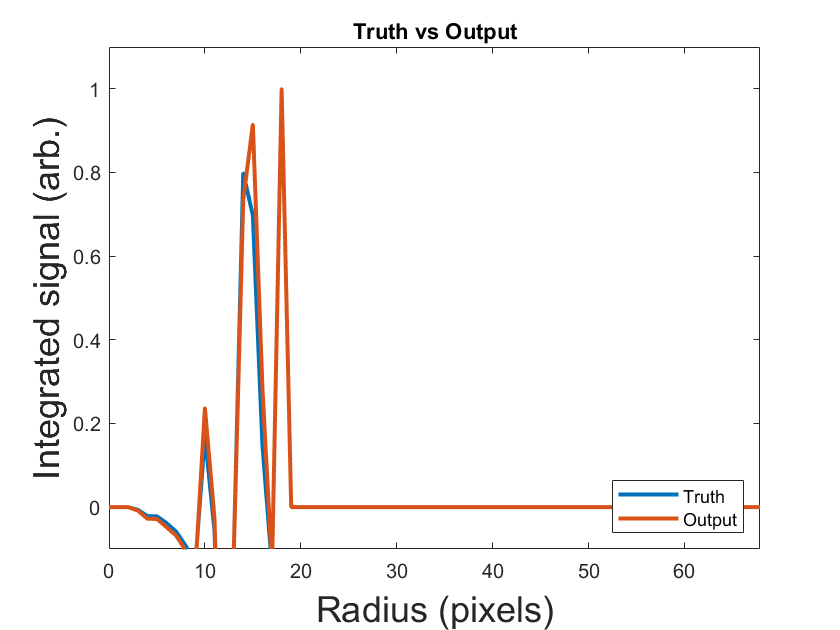



% % output + input on same graph
% figure()
% plot(radii, interp_integrated_output)
% hold on
% plot(radii, interp_integrated_input, "--")
% title("Velocity distributions - Output & Input")
% xlim([0, max(radii)])
% ylim([0, 1.1])
% xlabel("Radius (pixels)")
% ylabel("Integrated signal (arb.)")
% legend("Network output", "Network input", "Location", "northeast")

% truth vs output
figure()
plot(radii, interp_integrated_truth, "LineWidth", 2)
hold on
plot(radii, interp_integrated_output, "LineWidth", 2)
title("Truth vs Output")
xlim([0, max(radii)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)
legend("Truth", "Output", "location", "southeast")


% -----------------------------------------------------------------------------------------------

% % require this info from earlier
% x_res = 96;
% y_res = 96;
% x = linspace(-1, 1, x_res);
% y = linspace(-1, 1, y_res);
% [X, Y] = meshgrid(x, y);
% R = sqrt(X.^2 + Y.^2);
%
% cos_theta = Y./R;
%
% P2 = (1/2)*(3*cos_theta.^2 - 1);    %second legendre polynomial
% P4 = (1/8)*(35*cos_theta.^4 - 30*cos_theta.^2 + 3);     %fourth legendre polynomial
% P6 = (1/16)*(231*cos_theta.^6 - 315*cos_theta.^4 - 105*cos_theta.^2 - 5);   %sixth legendre polynomial


% find the original coefficients that comprised the rings

% % ring 1
% ring1_coeffs = coeffs.ring1;
%
% W1 = ring1_coeffs.W0;
% W1_N = W1(N);
%
% R2 = ring1_coeffs.R0;
% R1_N = R2(N);
%
% B21 = ring1_coeffs.B2;
% B21_N = B21(N);
%
% A01 = ring1_coeffs.A0;
% A01_N = A01(N);
%
% I1 = A01_N*exp(-((R-R1_N)/W1_N).^2).*(1 + B21_N*P2);
%
% showim(I1, 1)
% title("Ring 1")
%
% [integrated_I1, interp_integrated_I1, radii, radii_whole] = integrateim(I1);
%
% figure()
% % interp_integrated_I1 = interp_integrated_I1/max(interp_integrated_I1);
% plot(radii, interp_integrated_I1)
% title("Velocity distribution - Ring 1")
% xlim([0, max(radii)])
% ylim([0, 1.1])
% xlabel("Radius (pixels)")
% ylabel("Integrated signal (arb.)")


% % ring  2
% ring2_coeffs = coeffs.ring2;
%
% W2 = ring2_coeffs.W0;
% W2_N = W2(N);
%
% R2 = ring2_coeffs.R0;
% R2_N = R2(N);
%
% B22 = ring2_coeffs.B2;
% B22_N = B22(N);
%
% A02 = ring2_coeffs.A0;
% A02_N = A02(N);
%
% I2 = A02_N*exp(-((R-R2s_N)/W2_N).^2).*(1 + B22_N*P2);
%
% showim(I2, 1)
% title("Ring 2")
%
% [integrated_I2, interp_integrated_I2, radii, radii_whole] = integrateim(I2);
%
% figure()
% % interp_integrated_I2 = interp_integrated_I2/max(interp_integrated_I2);
% plot(radii, interp_integrated_I2)
% title("Velocity distribution - Ring 2")
% xlim([0, max(radii)])
% ylim([0, 1.1])
% xlabel("Radius (pixels)")
% ylabel("Integrated signal (arb.)")


% -----------------------------------------------------------------------------------------------
%
% % plot all images in the validation set
% for n = 1:20
%     showim(images_mat(:,:,n), 1)
%     title(n)
%     shading flat
% end



% % currently i need to use an image AFTER n = 10...
% % for silly reasons
%
% % set up coordinate system
% x_res = 96;
% y_res = 96;
% x = linspace(-1, 1, x_res);
% I_tot = linspace(-1, 1, y_res);
% [X, Y] = meshgrid(x, I_tot);
% R = sqrt(X.^2 + Y.^2);
%
% cos_theta = Y./R;
%
% P2 = (1/2)*(3*cos_theta.^2 - 1);    %second legendre polynomial
%
%
% A1 = coeffs.ring1.A0(N);
% A2 = coeffs.ring2.A0(N);
%
% R1 = coeffs.ring1.R0(N);
% R2 = coeffs.ring2.R0(N);
%
% W1 = coeffs.ring1.W0(N);
% W2 = coeffs.ring2.W0(N);
%
% B21 = coeffs.ring1.B2(N);
% B22 = coeffs.ring2.B2(N);
%
%
% I1 = A1*exp(-((R-R1)/W1).^2).*(1 + B21*P2);
%
% I2 = A2*exp(-((R-R2)/W2).^2).*(1 + B22*P2);
%
% I = I1 + I2;
%
% showim(I, 1)
% title("Original Simulation")


%
% B21 = -1;
%
% for i = 1:length(R_array_sorted)
%     R = R_array_sorted(i);
%     newI1(i) = A1*exp(-((R-R1)/W1).^2).*(1 + B21*P2new(i));
%     newI2(i) = A2*exp(-((R-R2)/W2).^2).*(1 + B22*P2new(i));
% end
%
% newI1 = A1*exp(-((R_array_sorted-R1)/W1).^2).*(1 + B21*P2new);
% newI2 = A2*exp(-((R_array_sorted-R2)/W2).^2).*(1 + B22*P2new);
% newI = newI1 + newI2;
%
% plot(theta_array_sorted, newI)

% % want to plot intensity vs angle initially
%
%
% % might need to weight the input
% inverted_output_new = inverted_output.*abs(X);
% % I_new = I1.*abs(X);
% I_new = I1;
%
% % angle
% % theta = acos(cos_theta);
% % theta_deg = rad2deg(theta);
% [theta, r] = cart2pol(X, Y);
% theta_deg = rad2deg(theta);
% theta_deg = theta_deg + 180;
% theta = deg2rad(theta_deg);
% theta_array = reshape(theta, 1, []);
% [theta_array_sorted, sorting] = sort(theta_array);
% theta_array_sorted_deg = rad2deg(theta_array_sorted);
% theta_array_sorted_deg_rounded = round(theta_array_sorted_deg,10);
% theta_array_sorted_deg_rounded_unique = unique(theta_array_sorted_deg_rounded);
%
% % reshape and sort the input the same way as the angle
% inverted_output_array = reshape(I_new, 1, []);
% inverted_output_array_sorted = inverted_output_array(sorting);
%
% % initialise an array
% integrated_over_theta = zeros(1, length(theta_array_sorted_deg_rounded_unique));
%
% % loop over all theta, average all points with same theta
% for i = 1:length(theta_array_sorted_deg_rounded_unique)
%     all_same_theta = theta_array_sorted_deg_rounded==theta_array_sorted_deg_rounded_unique(i);
%     integrated_over_theta(i) = mean(inverted_output_array_sorted(all_same_theta));
% end


showim(I,1)

Unrecognized function or variable 'I'.

title("Original")

% showim(I', 1)
% title("Transpose")


I_pol_original = cart_2_polar(I', [48,360]);
I_pol_original(I_pol_original<0) = 0;
showim(I_pol_original, 1)
title("Polar - Original Simulated (USE FOR RANGE)")
shading flat

range_min = 18;
range_max = 30;



I_pol_original = I_pol_original(6:175, range_min:range_max);
I_pol_original(I_pol_original<0) = 0;

showim(I_pol_original, 1)
title("Polar - Original Simulated")
shading flat


beta2_original = find_beta2(I, range_min, range_max);

plot(range_min:range_max, beta2_original)
title("Original Simulated")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-1, 2])


beta2_input = find_beta2(inverted_network_input, range_min, range_max);

I_pol = cart_2_polar(inverted_network_input', [48, 360]);
I_pol = I_pol(6:175, range_min:range_max);
I_pol(I_pol<0) = 0;
showim(I_pol, 1)
title("Polar - Input")
shading flat

plot(range_min:range_max, beta2_input)
title("Input")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-1, 2])


beta2_truth = find_beta2(inverted_truth, range_min, range_max);

I_pol = cart_2_polar(inverted_truth', [48, 360]);
I_pol = I_pol(6:175, range_min:range_max);
I_pol(I_pol<0) = 0;
showim(I_pol, 1)
title("Polar - Truth")
shading flat

plot(range_min:range_max, beta2_truth)
title("Truth")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-1, 2])


beta2_output = find_beta2(inverted_output, range_min, range_max);

I_pol = cart_2_polar(inverted_output', [48, 360]);
I_pol = I_pol(6:175, range_min:range_max);
I_pol(I_pol<0) = 0;
showim(I_pol, 1)
title("Polar - Output")
shading flat

plot(range_min:range_max, beta2_output)
title("Output")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-1, 2])


bin_size = 3;


[binned_beta2_original, error_original] = bin_beta2(beta2_original, bin_size);

radius_points = range_min:bin_size:range_max;

% plot(range_min+1:bin_size:range_max, binned_beta2_original, 'O', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r')
e = errorbar(radius_points(1:length(binned_beta2_original)), binned_beta2_original, error_original);
e.Marker = 'o';
e.MarkerEdgeColor = 'r';
e.MarkerFaceColor = 'r';
e.Color = 'r';
e.LineWidth = 1.5;
title("Original")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-1.1, 2.1])


[binned_beta2_input, error_input] = bin_beta2(beta2_input, bin_size);

% plot(range_min+1:bin_size:range_max, binned_beta2_input, 'O', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r')
e = errorbar(radius_points(1:length(binned_beta2_input)), binned_beta2_input, error_input);
e.Marker = 'o';
e.MarkerEdgeColor = 'r';
e.MarkerFaceColor = 'r';
e.Color = 'r';
e.LineWidth = 1.5;
title("Input")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-1.1, 2.1])


[binned_beta2_truth, error_truth] = bin_beta2(beta2_truth, bin_size);

% plot(range_min+1:bin_size:range_max, binned_beta2_truth, 'O', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r')
e = errorbar(radius_points(1:length(binned_beta2_truth)), binned_beta2_truth, error_truth);
e.Marker = 'o';
e.MarkerEdgeColor = 'r';
e.MarkerFaceColor = 'r';
e.Color = 'r';
e.LineWidth = 1.5;
title("Truth")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-1.1, 2.1])


[binned_beta2_output, error_output] = bin_beta2(beta2_output, bin_size);

% plot(range_min+1:bin_size:range_max, binned_beta2_output, '.', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r')
e = errorbar(radius_points(1:length(binned_beta2_output)), binned_beta2_output, error_output);
e.Marker = 'o';
e.MarkerEdgeColor = 'r';
e.MarkerFaceColor = 'r';
e.Color = 'r';
e.LineWidth = 1.5;

title("Output")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-1.1, 2.1])




f = errorbar(radius_points(1:length(binned_beta2_original)), binned_beta2_original, error_original);
f.Marker = 'o';
f.MarkerEdgeColor = 'b';
f.MarkerFaceColor = 'b';
f.Color = 'b';
f.LineWidth = 1.5;
hold on
% plot(range_min+1:bin_size:range_max, binned_beta2_output,'O', 'MarkerFaceColor', 'r', 'MarkerEdgeColor', 'r')
e = errorbar(radius_points(1:length(binned_beta2_output)), binned_beta2_output, error_output);
e.Marker = 'o';
e.MarkerEdgeColor = 'r';
e.MarkerFaceColor = 'r';
e.Color = 'r';
e.LineWidth = 1.5;
hold off
title("Original vs Output")
xlabel("Radius")
ylabel("Beta2 Parameter")
xlim([0, 48])
ylim([-2, 3])
legend("Original", "Output")


% plot(range_min+1:bin_size:range_max, binned_beta2_original, 'x')
% hold on
% plot(range_min+1:bin_size:range_max, binned_beta2_input, 'x')
% plot(range_min+1:bin_size:range_max, binned_beta2_truth, 'x')
% plot(range_min+1:bin_size:range_max, binned_beta2_output, 'x')
% hold off
% title("")
% xlabel("Radius")
% ylabel("Beta2 Parameter")
% xlim([0, 48])
% ylim([-1, 2])
% legend("Original", "Input", "Truth", "Output")



% output

figure()
% plot on top of velocity distributions!
yyaxis left
plot(radii, interp_integrated_output, "LineWidth", 2)
% title("Velocity distribution - Network output (with B2)")
xlim([0, max(radii)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

yyaxis right
e = errorbar(radius_points(1:length(binned_beta2_output)), binned_beta2_output, error_output);
ylim([-1.2, 2.2])
ylabel("\beta_2 Parameter", "FontSize", 18)
% legend("Velocity Distribution", "\beta_2 Parameter")
e.Marker = 'o';
e.MarkerEdgeColor = 'r';
e.MarkerFaceColor = 'r';
e.Color = 'r';
e.LineWidth = 1.5;

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';



% truth
figure()
yyaxis left
plot(radii, interp_integrated_truth, "LineWidth", 2)
xlim([0, max(radii)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

yyaxis right
e = errorbar(radius_points(1:length(binned_beta2_input)), binned_beta2_truth, error_truth);
ylim([-1.2, 2.2])
ylabel("\beta_2 Parameter", "FontSize", 18)
% legend("Velocity Distribution", "\beta_2 Parameter")
e.Marker = 'o';
e.MarkerEdgeColor = 'r';
e.MarkerFaceColor = 'r';
e.Color = 'r';
e.LineWidth = 1.5;

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';



% input
figure()
yyaxis left
plot(radii, interp_integrated_input, "LineWidth", 2)
xlim([0, max(radii)])
ylim([-0.1, 1.1])
xlabel("Radius (pixels)", "FontSize", 18)
ylabel("Integrated signal (arb.)", "FontSize", 18)

yyaxis right
e = errorbar(radius_points(1:length(binned_beta2_input)), binned_beta2_input, error_input);
ylim([-1.2, 2.2])
ylabel("\beta_2 Parameter", "FontSize", 18)
% legend("Velocity Distribution", "\beta_2 Parameter")
e.Marker = 'o';
e.MarkerEdgeColor = 'r';
e.MarkerFaceColor = 'r';
e.Color = 'r';
e.LineWidth = 1.5;

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';


